# FOM热力学参数辨识

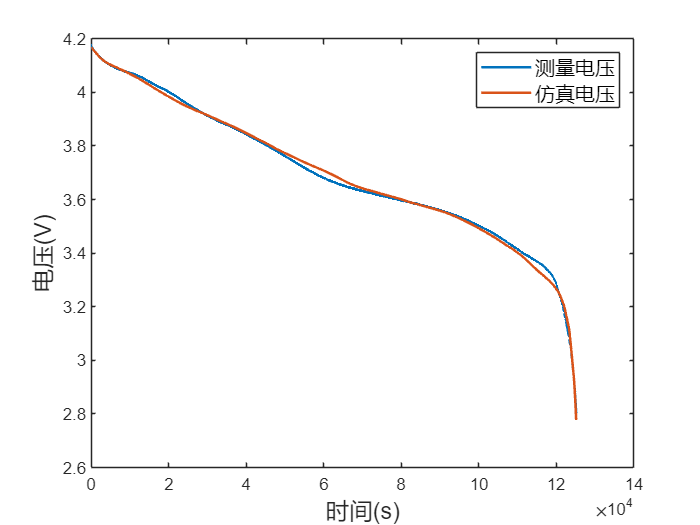

clear;
clc;

load nmc1_30.mat;
I=nmc1_30.Cur;
V=nmc1_30.Vol;
t=nmc1_30.t;
Q=nmc1_30.Q;

% setting = optimoptions('particleswarm','SwarmSize',500,'Display','iter','MaxIterations',500);
% [x,evalu] = particleswarm(@findre,4,[0,0,0,0],[1,5,1,5],setting)
% x=fminunc(@findre,[0.2,4.8,0.4,9],optimset)
x=[0.278341730585941,3.61137408174925,0.987069383657047,2.70544455127934];
% x=[0.26,3.61137408174925,0.9966,2.70544455127934];
% 
change_thetap=Q/1000;
theta_p1=x(1)+change_thetap/x(2);

change_thetan=Q/1000;
theta_n1=x(3)-change_thetan/x(4);

Vsim=Eeq_NMC(theta_p1)-Eeq_MCMB(theta_n1);

figure(1);
clf;
plot(V,LineWidth=1.5);
hold on;
plot(Vsim,LineWidth=1.5);
legend('测量电压','仿真电压',fontsize=12);
xlabel('时间(s)','fontsize',14);
ylabel('电压(V)','fontsize',14);

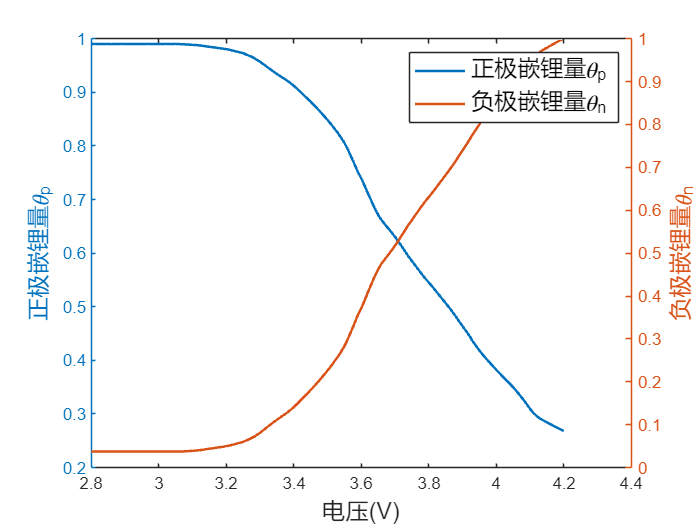

Error(1)=RMSE(Vsim,V)*1000;
Error(2)=MAPE(Vsim,V);

Vsearch=2.8:0.01:4.2;
for i=1:length(Vsearch)
    [thetap_search(i),thetan_search(i)]=bisearch(Vsearch(i),x);
end
figure(2);
clf;
yyaxis left;
plot(Vsearch,thetap_search,LineWidth=1.5);
ylabel('正极嵌锂量\theta_p','fontsize',14);
yyaxis right;
plot(Vsearch,thetan_search,LineWidth=1.5);
ylim([0,1]);
legend('正极嵌锂量\theta_p','负极嵌锂量\theta_n',fontsize=14);
xlabel('电压(V)','fontsize',14);
ylabel('负极嵌锂量\theta_n','fontsize',14);